# ADMIRE Simulator Output Visualization Examples

The open-source Aero-Data Model In a Research Environment (ADMIRE) in MATLAB/Simulink.

The ADMIRE describes a generic small single-seated, single-engine fighter aircraft with a delta-canard configuration (just like the Saab 39 Gripen). The plant is augmented with a longitudinal Flight Control System ([#FCS](https://www.linkedin.com/feed/hashtag/?keywords=fcs&highlightedUpdateUrns=urn%3Ali%3Aactivity%3A6743635511929262080)) that [#controls](https://www.linkedin.com/feed/hashtag/?keywords=controls&highlightedUpdateUrns=urn%3Ali%3Aactivity%3A6743635511929262080) the pitch rate at low speed and the load factor at higher speeds, and a lateral controller that controls the wind vector roll rate and the angle of sideslip. The model has thrust vectoring capability, although this is not used in the present FCS.

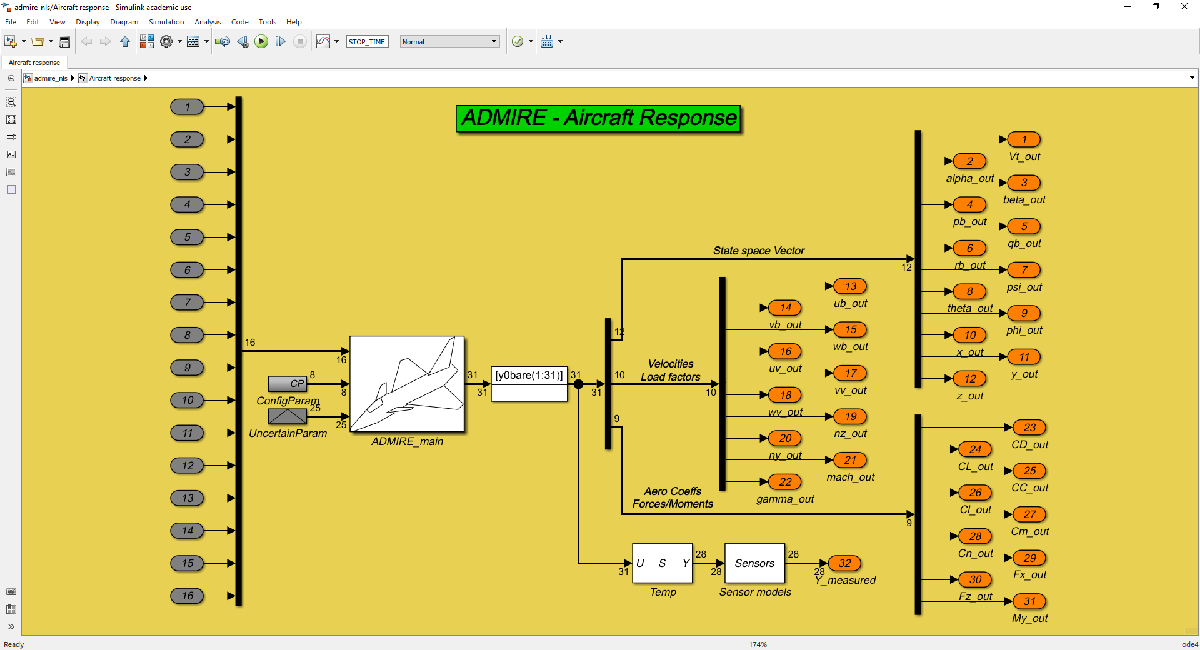

## Example Script to Visualize the ADMIRE Simulation Output

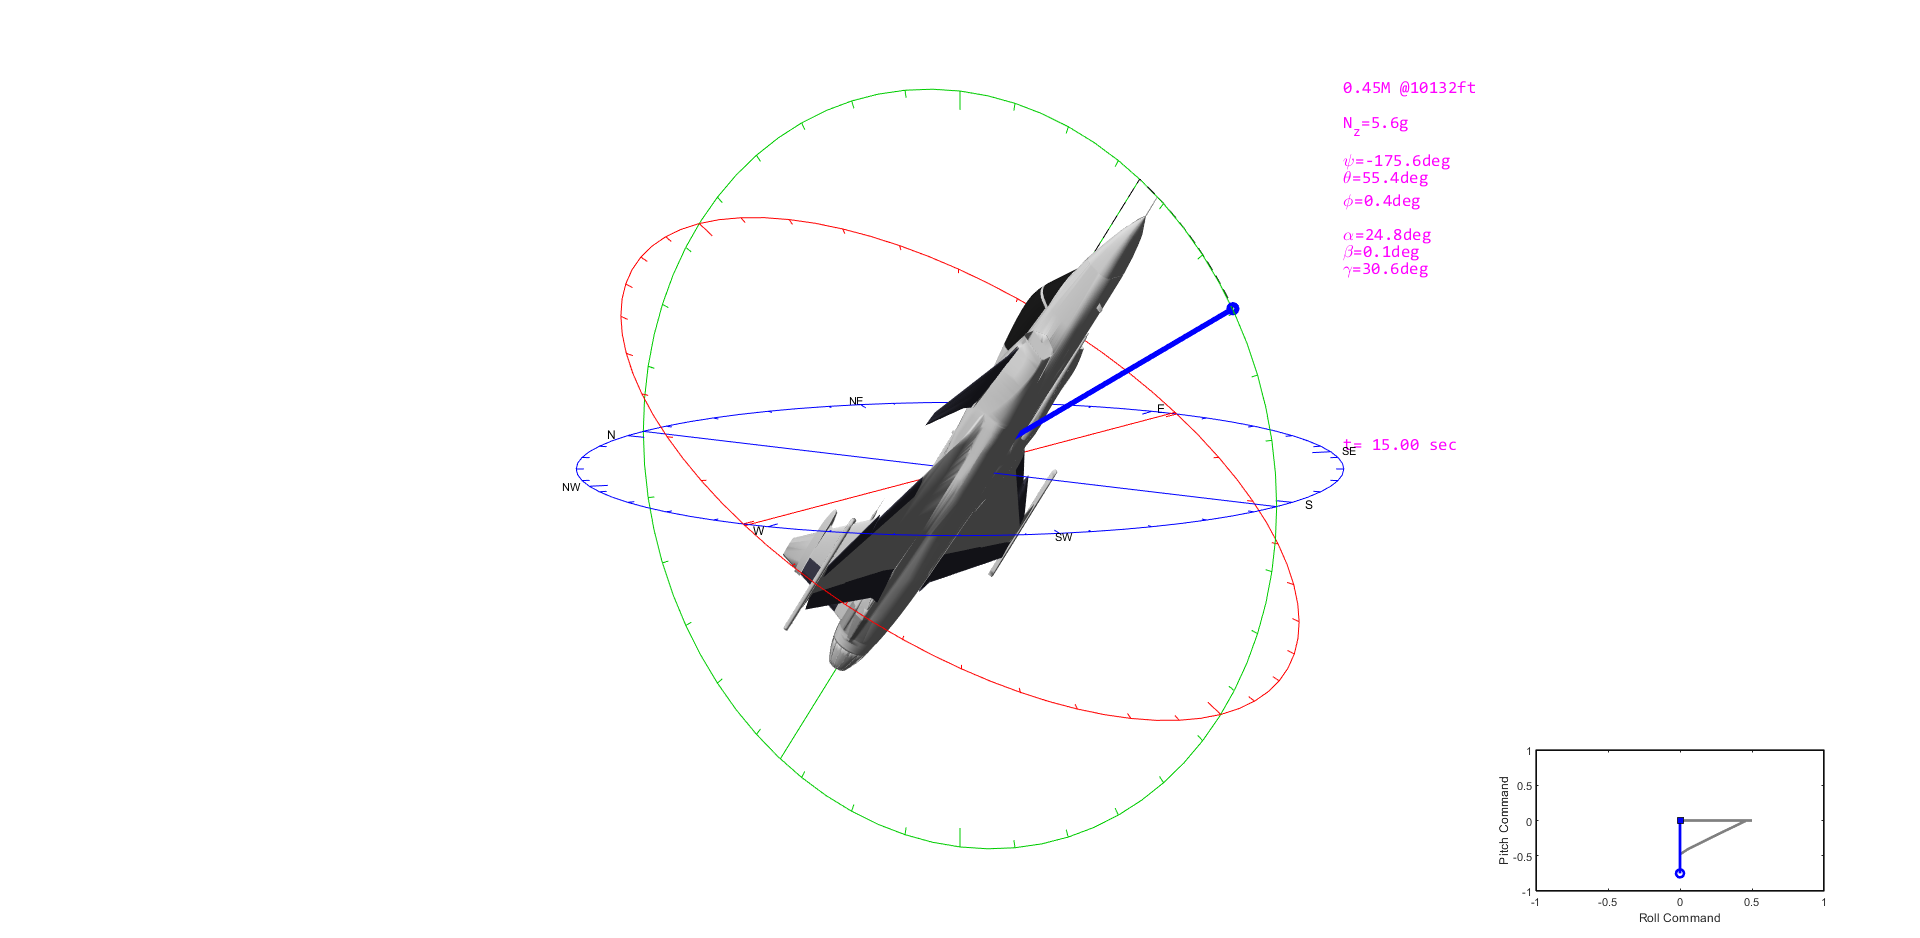

Elapsed time is 15.070437 seconds.


% Add path to the simulation outputs
addpath('./simulation_data/')

% path of the *.mat file containing the 3d model information
model_info_file = 'SAAB_GRIPEN_MULTI_BODY.mat';

% Load the simulation data
% load('scissors_maneuver.mat')
% load('breakaway_maneuver.mat')
load('split_s_maneuver.mat')
% load('departure.mat')

% Decrease the sampling rate (get 1 each 4 samples)
tout = tout(1:4:end);
yout = yout(1:4:end, :);
stick = stick(1:4:end, :);
act = act(1:4:end, :);

% define the reproduction speed factor
speedx = 1; 

% Do you want to save the animation in a mp4 file? (0.No, 1.Yes)
isave_movie = 0;

% Movie file name
movie_file_name = '';

% -------------------------------------------------------------------------
% The frame sample time shall be higher than 0.02 seconds to be able to 
% update the figure (CPU/GPU constraints)
frame_sample_time = max(0.02, tout(2)-tout(1));

% Resample the time vector to modify the reproduction speed
t_new   = tout(1):frame_sample_time*(speedx):tout(end);
% Resample the recorded data
act     = interp1(tout, act, t_new',   'linear');
stick   = interp1(tout, stick, t_new', 'linear');
y_new   = interp1(tout, yout, t_new',  'linear');

% We have to be careful with angles with limited ranges
y_new(:, 7)  = atan2(interp1(tout, sin(yout(:, 7)), t_new', 'linear'), interp1(tout, cos(yout(:, 7)), t_new','linear')) * 180 / pi;
y_new(:, 8)  = atan2(interp1(tout, sin(yout(:, 8)), t_new', 'linear'), interp1(tout, cos(yout(:, 8)), t_new','linear')) * 180 / pi;
y_new(:, 9)  = atan2(interp1(tout, sin(yout(:, 9)), t_new', 'linear'), interp1(tout, cos(yout(:, 9)), t_new','linear')) * 180 / pi;

% Assign the data
heading_deg           =  y_new(:, 7);
pitch_deg             =  y_new(:, 8);
bank_deg              =  y_new(:, 9);
roll_command          = -stick(:, 2);
pitch_command         = -stick(:, 1);
angle_of_attack_deg   =  y_new(:, 2) * 180 / pi;
angle_of_sideslip_deg =  y_new(:, 3) * 180 / pi;
fligh_path_angle_deg  =  y_new(:, 22) * 180 / pi;
mach                  =  y_new(:, 21);
altitude_ft           = -y_new(:, 12);
nz_g                  =  y_new(:, 19);

% Flight control surfaces
le     = act(:, 9);
dr     = act(:, 8);
df1    = act(:, 6);
df2    = act(:, 5);
df3    = act(:, 4);
df4    = act(:, 3);
dfp    = 0.5 * (act(:, 1) + act(:, 2));

% Control array assignation
% (modify the order according to your particular 3D model)
controls_deflection_deg = [ dfp(:), dfp(:), le(:), le(:), dr(:), 0.5*(df1(:)+df2(:)), 0.5*(df3(:)+df4(:))];

%% Run aircraft_3d_animation function
% -------------------------------------------------------------------------
aircraft_3d_animation(model_info_file,...
    heading_deg, ...            Heading angle [deg]
    pitch_deg, ...              Pitch angle [deg]
    bank_deg, ...               Roll angle [deg]
    roll_command, ...           Roll  stick command [-1,+1] [-1 -> left,            +1 -> right]
    pitch_command, ...          Pitch stick command [-1,+1] [-1 -> full-back stick, +1 -> full-fwd stick]
    angle_of_attack_deg, ...    AoA [deg]
    angle_of_sideslip_deg, ...  AoS [deg]
    fligh_path_angle_deg, ...   Flight path angle [deg]
    mach, ...                   Mach number
    altitude_ft, ...            Altitude [ft]
    nz_g,  ...                  Vertical load factor [g]
    controls_deflection_deg, ...Flight control deflection (each column is a control surface)
    frame_sample_time, ...      Sample time [sec]
    speedx, ...                 Reproduction speed
    isave_movie, ...            Save the movie? 0-1
    movie_file_name);           % Movie file name

# Multi-agent 3D Animations